# Question 8.7 Solution

clear all
close all

In this problem we consider the derivatives both finite difference and spectral methods of the following functions


$$\begin{array}{lcl}

f_{1}(x)&=&|x^{3}|\\
f_{2}(x)&=&\exp{(-x^{-2})}\\
f_{3}(x)&=&\frac{1}{1+x^{2}}\\
f_{4}(x)&=&x^{10}


\end{array}$$


Plotting in MATLAB, we see that these functions have the form

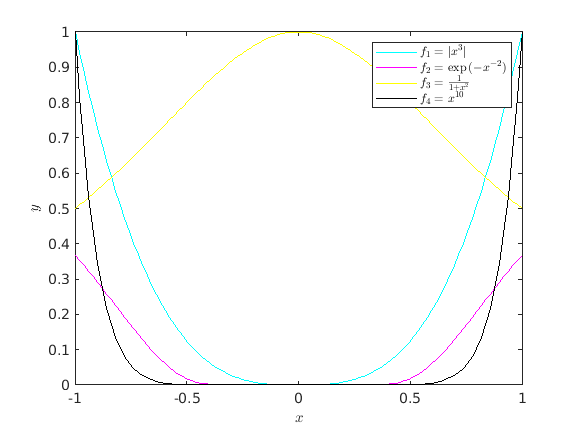

f1 = @(x) abs(x.^3);
f2 = @(x) exp(-x.^(-2));
f3 = @(x) 1./(1+x.^2);
f4 = @(x) x.^10;

x = linspace(-1,1,100);

plot(x,f1(x),'c')
hold on
plot(x,f2(x),'m')
plot(x,f3(x),'y')
plot(x,f4(x),'k')
hold off
xlabel('$x$','interpreter','latex')
ylabel('$y$','interpreter','latex')
legend('$f_{1}=|x^{3}|$','$f_{2}=\exp{(-x^{-2})}$','$f_{3}=\frac{1}{1+x^{2}}$','$f_{4}=x^{10}$','interpreter','latex')

To compute the derivatives numerically, we first need to compute the derivative matrices. For a central difference method with a singled sided difference at the ends, these usually have the form 


$$[D]
=
\frac{1}{\Delta}
\left[
\begin{array}{ccc}
-1 & 1 \\
&\ddots & \ddots\\
& -1/2 & 0 & 1/2\\
& & \ddots&\ddots\\
& & & -1 & 1
\end{array}
\right]$$


I'll refer you to Lecture 14.1 for the derivation in the 4 point case.

So to implement a function $\texttt{DerivMatrix\_FD()}$ to compute the $N+1$ point finite difference derivative matrix, we have

The loop here first applies the central difference template $[-1/2,0,1/2]$ to rows $2$ to $N$, then the single sided difference template $[-1,1]$ is applied to first and last rows, corresponding to the top-left and bottom-right corners.

For a $10$ point case, where we've set $\Delta=1$, the derivative matrix has the form

DerivMatrix_FD(1,9)

ans =    -1.0000    1.0000         0         0         0         0         0         0         0         0
   -0.5000         0    0.5000         0         0         0         0         0         0         0
         0   -0.5000         0    0.5000         0         0         0         0         0         0
         0         0   -0.5000         0    0.5000         0         0         0         0         0
         0         0         0   -0.5000         0    0.5000         0         0         0         0
         0         0         0         0   -0.5000         0    0.5000         0         0         0
         0         0         0         0         0   -0.5000         0    0.5000         0         0
         0         0         0         0         0         0   -0.5000         0    0.5000         0
         0         0         0         0         0         0         0   -0.5000         0    0.5000
         0         0         0         0         0         0         0         0   -1

Now for a spectral method, we'll apply the function $\texttt{DerivMatrix()}$ from Lecture 14.2, which we've renamed as $\texttt{DerivMatrix\_SD()}$ for clarity sake. As a reminder, the spectral derivative matrix computes the derivative of the Lagrange basis polynomials at each of the interpolation nodes


$$[D]
=
\left
[
\begin{array}{ccc}
L'_{0}(x_{0}) & \cdots & L'_{N}(x_{0})\\
\vdots & \ddots & \vdots \\
L'_{0}(x_{N}) & \cdots & L'_{N}(x_{N})
\end{array}
\right]$$


Using $10$ evenly spaced points, the derivative matrix is therefore

xnodes = linspace(-1,1,10);
DerivMatrix_SD(xnodes,9)

ans =   -12.7304   40.5000  -81.0000  126.0000 -141.7500  113.4000  -63.0000   23.1429   -5.0625    0.5000
   -0.5000   -7.7304   18.0000  -21.0000   21.0000  -15.7500    8.4000   -3.0000    0.6429   -0.0625
    0.0625   -1.1250   -4.9179   10.5000   -7.8750    5.2500   -2.6250    0.9000   -0.1875    0.0179
   -0.0179    0.2411   -1.9286   -2.7750    6.7500   -3.3750    1.5000   -0.4821    0.0964   -0.0089
    0.0089   -0.1071    0.6429   -3.0000   -0.9000    4.5000   -1.5000    0.4286   -0.0804    0.0071
   -0.0071    0.0804   -0.4286    1.5000   -4.5000    0.9000    3.0000   -0.6429    0.1071   -0.0089
    0.0089   -0.0964    0.4821   -1.5000    3.3750   -6.7500    2.7750    1.9286   -0.2411    0.0179
   -0.0179    0.1875   -0.9000    2.6250   -5.2500    7.8750  -10.5000    4.9179    1.1250   -0.0625
    0.0625   -0.6429    3.0000   -8.4000   15.7500  -21.0000   21.0000  -18.0000    7.7304    0.5000
   -0.5000    5.0625  -23.1429   63.0000 -113.4000  141.7500 -126.0000   81.0000  -40

Now to approximate derivatives, the idea of using derivative matrices is to multiply a vector of the original function values $\{f\}$ by $[D]$ to give a vector of the numerical derivatives $\{f'\}$

So, the first step is to therefore define the points of interest, for both cases we'll consider using $10$ evenly spaced points 

M = 9;
xnodes = linspace(-1,1,M+1)';

Then, the derivative matrices can be computed using

delta = xnodes(2)-xnodes(1);
FD = DerivMatrix_FD(delta,M);
SD = DerivMatrix_SD(xnodes,M);

And finally, the derivatives are computed using 


$$\{f'\}=[D]\{f\}$$


So

FD1 = FD*f1(xnodes);
FD2 = FD*f2(xnodes);
FD3 = FD*f3(xnodes);
FD4 = FD*f4(xnodes);

SD1 = SD*f1(xnodes);
SD2 = SD*f2(xnodes);
SD3 = SD*f3(xnodes);
SD4 = SD*f4(xnodes);

It turns out that exact derivatives exist for $f_{1}$ to $f_{4}$ and are given by


$$\begin{array}{ccc}

f'_{1}(x)&=&3x|x|\\
f'_{2}(x)&=&\frac{2f_{2}(x)}{x^{3}}\\
f'_{3}(x)&=&-2xf_{3}(x)^2\\
f'_{4}(x)&=&10x^{9}

\end{array}$$


So plotting the numerical approximations with the exact derivatives, we find

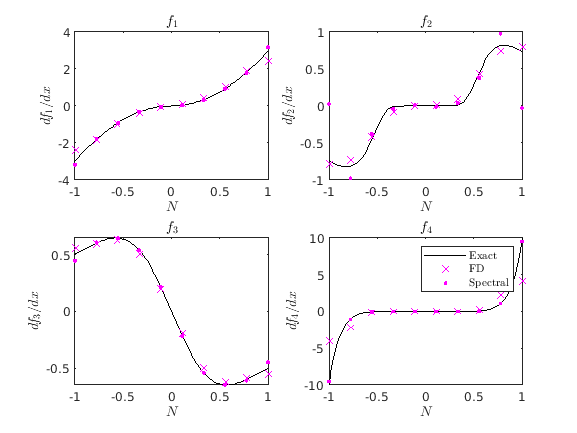

functions = {'$f_{1}$','$f_{2}$','$f_{3}$','$f_{4}$'};

f1_prime = @(x) 3*x.*abs(x);
f2_prime = @(x) 2.*exp(-x.^(-2))./x.^3;
f3_prime = @(x) -2*x.*f3(x).^2;
f4_prime = @(x) 10*x.^9;

x = linspace(-1,1,100);

subplot(2,2,1)
plot(x,f1_prime(x),'k')
hold on
plot(xnodes,FD1,'xm')
plot(xnodes,SD1,'.m')
hold off
xlabel('$N$','Interpreter','latex')
ylabel('$df_{1}/dx$','Interpreter','latex')
title(functions{1},'Interpreter','latex')
subplot(2,2,2)
plot(x,f2_prime(x),'k')
hold on
plot(xnodes,FD2,'xm')
plot(xnodes,SD2,'.m')
hold off
xlabel('$N$','Interpreter','latex')
ylabel('$df_{2}/dx$','Interpreter','latex')
title(functions{2},'Interpreter','latex')
subplot(2,2,3)
plot(x,f3_prime(x),'k')
hold on
plot(xnodes,FD3,'xm')
plot(xnodes,SD3,'.m')
hold off
xlabel('$N$','Interpreter','latex')
ylabel('$df_{3}/dx$','Interpreter','latex')
title(functions{3},'Interpreter','latex')
subplot(2,2,4)
plot(x,f4_prime(x),'k')
hold on
plot(xnodes,FD4,'xm')
plot(xnodes,SD4,'.m')
hold off
xlabel('$N$','Interpreter','latex')
ylabel('$df_{4}/dx$','Interpreter','latex')
title(functions{4},'Interpreter','latex')
legend('Exact','FD','Spectral','interpreter','latex')

To measure the convergence, we wrap the previous code segments in a loop, which recomputes the nodes, derivative matrix, and derivatives for orders up to $30$, giving

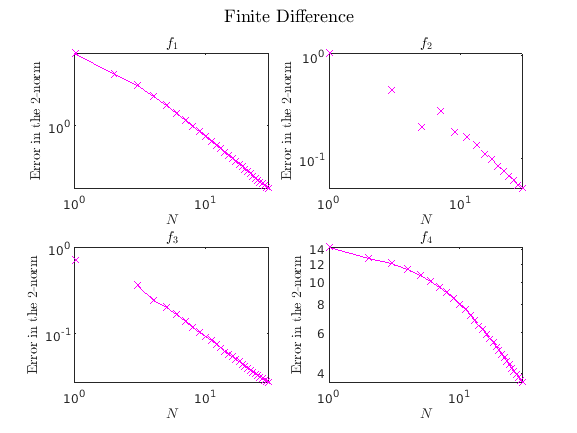

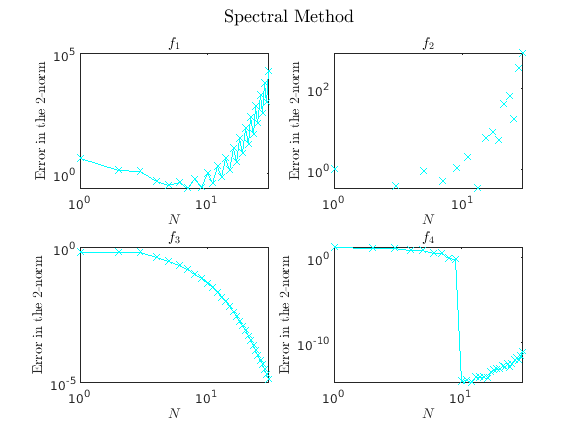

M = 30;
error_FD = zeros(4,M);
error_SD = zeros(4,M);

for N = 1:M
    xnodes = linspace(-1,1,N+1)';
    delta = xnodes(2)-xnodes(1);
    FD = DerivMatrix_FD(delta,N);
    SD = DerivMatrix_SD(xnodes,N);
    
    error_FD(1,N) = norm(f1_prime(xnodes)-FD*f1(xnodes),2);
    temp_FD = f2_prime(xnodes)-FD*f2(xnodes);
    error_FD(2,N) = norm(temp_FD(~isinf(temp_FD)),2);
    error_FD(3,N) = norm(f3_prime(xnodes)-FD*f3(xnodes),2);
    error_FD(4,N) = norm(f4_prime(xnodes)-FD*f4(xnodes),2);
    
    error_SD(1,N) = norm(f1_prime(xnodes)-SD*f1(xnodes),2);
    temp_SD = f2_prime(xnodes)-SD*f2(xnodes);
    error_SD(2,N) = norm(temp_SD(~isinf(temp_SD)),2);
    error_SD(3,N) = norm(f3_prime(xnodes)-SD*f3(xnodes),2);
    error_SD(4,N) = norm(f4_prime(xnodes)-SD*f4(xnodes),2);
end



for i=1:4
    figure(21)
    subplot(2,2,i)
    loglog(1:M,error_FD(i,:),'x-m')
    xlabel('$N$','Interpreter','latex')
    ylabel('Error in the 2-norm','Interpreter','latex')
    title(functions{i},'Interpreter','latex')
    sgtitle('Finite Difference','Interpreter','latex')
   
    figure(22)
    subplot(2,2,i)
    loglog(1:M,error_SD(i,:),'x-c')
    xlabel('$N$','Interpreter','latex')
    ylabel('Error in the 2-norm','Interpreter','latex')
    title(functions{i},'Interpreter','latex')
    sgtitle('Spectral Method','Interpreter','latex')
   
end

We can see that with the finite difference method there is a steady decline in the error as the number of points increases. However, for the spectral method, while we do see the exponential convergence we expect for $f_{3}$, and an error of almost machine precision for $f_{4}$ due to it being a polynomial, the functions $f_{1}$ and $f_{2}$ don't behave nearly as well, mainly due to the use of evenly spaced nodes.

To illustrate this we'll now recompute error using both Gauss-Lobatto and Gauss-Legendre points

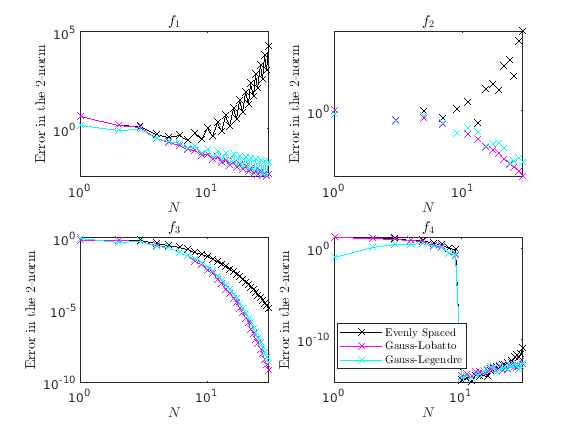

error_Even = zeros(4,M);
error_GLo = zeros(4,M);
error_GLe = zeros(4,M);

for N = 1:M
    xGLo = GLL_nodes(N);
    xGLe = gauss_legendre_points(N+1);
    xEven = linspace(-1,1,N+1)';
    SD_Even = DerivMatrix_SD(xEven,N);
    SD_GLo = DerivMatrix_SD(xGLo,N);
    SD_GLe = DerivMatrix_SD(xGLe,N);
    
    error_Even(1,N) = norm(f1_prime(xEven)-SD_Even*f1(xEven),2);
    temp_FD = f2_prime(xEven)-SD_Even*f2(xEven);
    error_Even(2,N) = norm(temp_FD(~isinf(temp_FD)),2);
    error_Even(3,N) = norm(f3_prime(xEven)-SD_Even*f3(xEven),2);
    error_Even(4,N) = norm(f4_prime(xEven)-SD_Even*f4(xEven),2);
    
    error_GLo(1,N) = norm(f1_prime(xGLo)-SD_GLo*f1(xGLo),2);
    temp_SD = f2_prime(xGLo)-SD_GLo*f2(xGLo);
    error_GLo(2,N) = norm(temp_SD(~isinf(temp_SD)),2);
    error_GLo(3,N) = norm(f3_prime(xGLo)-SD_GLo*f3(xGLo),2);
    error_GLo(4,N) = norm(f4_prime(xGLo)-SD_GLo*f4(xGLo),2);
    
    error_GLe(1,N) = norm(f1_prime(xGLe)-SD_GLe*f1(xGLe),2);
    temp_SD = f2_prime(xGLe)-SD_GLe*f2(xGLe);
    error_GLe(2,N) = norm(temp_SD(~isinf(temp_SD)),2);
    error_GLe(3,N) = norm(f3_prime(xGLe)-SD_GLe*f3(xGLe),2);
    error_GLe(4,N) = norm(f4_prime(xGLe)-SD_GLe*f4(xGLe),2);
end


figure(101)
for i=1:4
    
    subplot(2,2,i)    
    loglog(1:M,error_Even(i,:),'x-k')
    hold on
    loglog(1:M,error_GLo(i,:),'x-m')
    loglog(1:M,error_GLe(i,:),'x-c')
    hold off
    xlabel('$N$','Interpreter','latex')
    ylabel('Error in the 2-norm','Interpreter','latex')
    title(functions{i},'Interpreter','latex')
   
end
legend('Evenly Spaced','Gauss-Lobatto','Gauss-Legendre','interpreter','latex','location','best')

We see that using the unevenly spaced node sets gives much better results as expected.

function D = DerivMatrix_FD(delta,N)
    D = zeros(N+1,N+1);
   
    for k = 2:N
        D(k,k-1:k+1) = [-1/2,0,1/2];
    end
    D(1,1:2) = [-1,1];
    D(end,end-1:end) = [-1,1];
    D = D/delta;
end

function D=DerivMatrix_SD(x,n)
D=zeros(n+1,n+1);
for i=1:n+1
    num(i)=1.0;
    for k=1:n+1
        if k ~= i
            num(i)=num(i)*(x(i)-x(k));
        end
    end
end
for j=1:n+1
    den(j)=1.0;
    for k=1:n+1
        if k ~= j
            den(j)=den(j)*(x(j)-x(k));
        end
    end
end
for i=1:n+1
    for j=1:n+1
        if i ~= j
            D(i,j)=num(i)/(den(j)*(x(i)-x(j)));
        end
    end
end
for i=1:n+1
    for k=1:n+1
        if i~=k
            D(i,i)=D(i,i)+1./(x(i)-x(k));
        end
    end
end
end

function x = gauss_legendre_points(k)
syms t
x = double(vpasolve(legendreP(k,t) == 0));
end

function xp = GLL_nodes(N)
    
    syms x
    Lo = (1-x^2)*diff(legendreP(N,x),x);
    xp = double(vpasolve(Lo == 0));
    
end